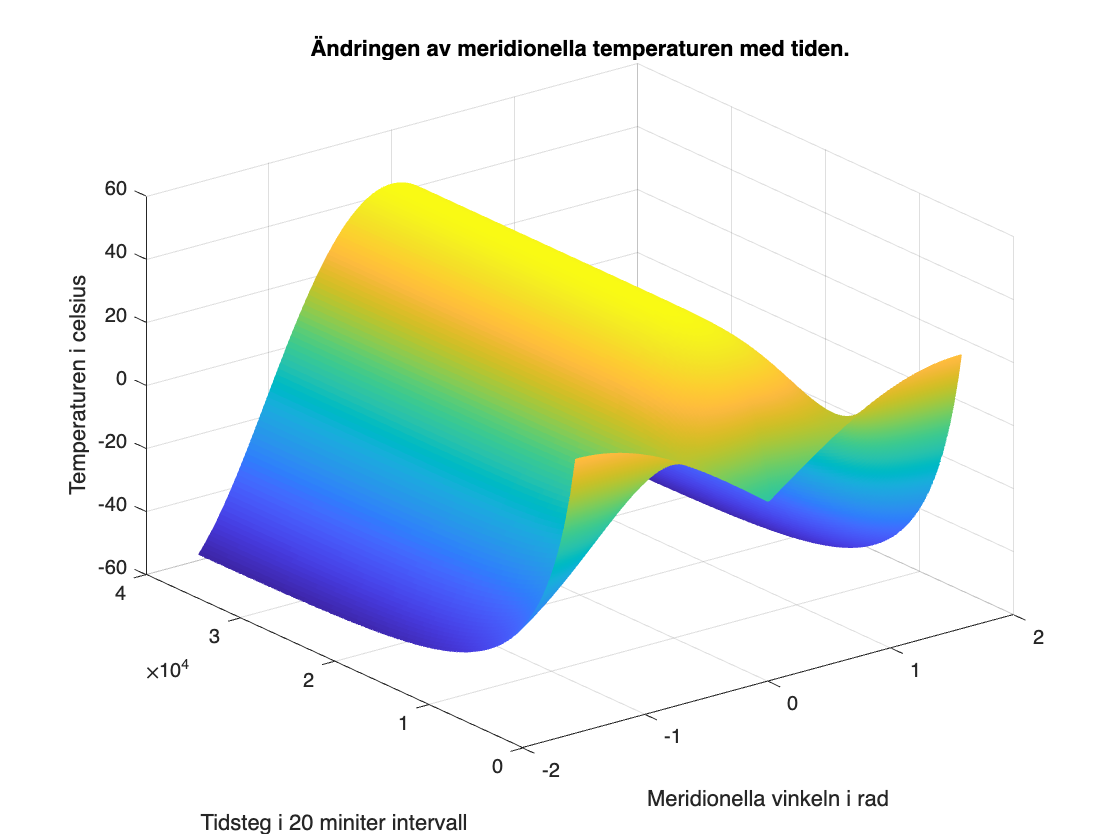

S0 = 1367;
h = 8.3*1000;
rho = 1.2;
c = 1000;
epsilon = 0.6;
sigma = 5.67 * 10^(-8);
R = 6371*1000;

fisteg = 180;
dfi = pi /fisteg;
dt = 60*20;
N = 20000;

lat = linspace(-pi/2, pi/2, fisteg);

Tmatrix = zeros(N, fisteg);
Tmatrix(1,:) = 270 + 30*abs(cos(lat-pi/2));

K = @(fi) 0;%(1.5 + 2.5.*cos(fi)) .*10^6;
Kprim = @(fi) 0;%- 2.5.*sin(fi).*10^6;
alpha = @(fi) 0.6 - 0.4.*cos(fi);
S = @(fi) S0 * (0.5294 + 0.706 .*(cos(fi).^2));

A = (1-alpha(lat)).*S(lat)./(4*h*rho*c); %konstant term
B = (epsilon*sigma)/(h*rho*c); %konstant framför T^4
C = zeros(180); %finita differans matris

for k = 2:fisteg-1
    C(k,k-1:k+1) = (1/(R^2 * dfi))*[-Kprim(lat(k))+K(lat(k))*tan(lat(k)) + (K(lat(k))/dfi), Kprim(lat(k))-K(lat(k))*tan(lat(k)) - (2*K(lat(k))/dfi), K(lat(k))/dfi];
end

%randvärden
C(1,1:2) = (1/(R^2 * dfi^2))*[-K(lat(1)),K(lat(1))];
C(180,179:180) = (1/(R^2 * dfi^2))*[K(lat(180)),-K(lat(180))];
C(179,178:180) = (1/(R^2 * dfi))*[ -Kprim(lat(179))+K(lat(179))*tan(lat(179)) + (K(lat(179))/dfi) ,Kprim(lat(179))-K(lat(179))*tan(lat(179)) - (K(lat(179))/dfi), 0];

C = C';

for i = 1:N-1
    
    TNew = (A - (Tmatrix(i,:).^4)*B + Tmatrix(i,:)*C)*dt + Tmatrix(i,:);

    Tmatrix(i+1,:) = TNew;
end

%% plot
figure(1)
timeVec = linspace(1,N,N);
%colormap('hot')
mesh(lat, timeVec,Tmatrix-273)
maxTemp = max(Tmatrix, [], 'all');
maxTemp = maxTemp-273;
xlabel('Meridionella vinkeln i rad') 
ylabel('Tidsteg i 20 miniter intervall')
zlabel('Temperaturen i celsius')
title('Ändringen av meridionella temperaturen med tiden.')


fprintf('Maxtemperaturen vid ekvatorn efter %f år är %f grader Celsuis \n', round(dt*N)/31556926, maxTemp)

Maxtemperaturen vid ekvatorn efter 1.521061 år är 42.653843 grader Celsuis 


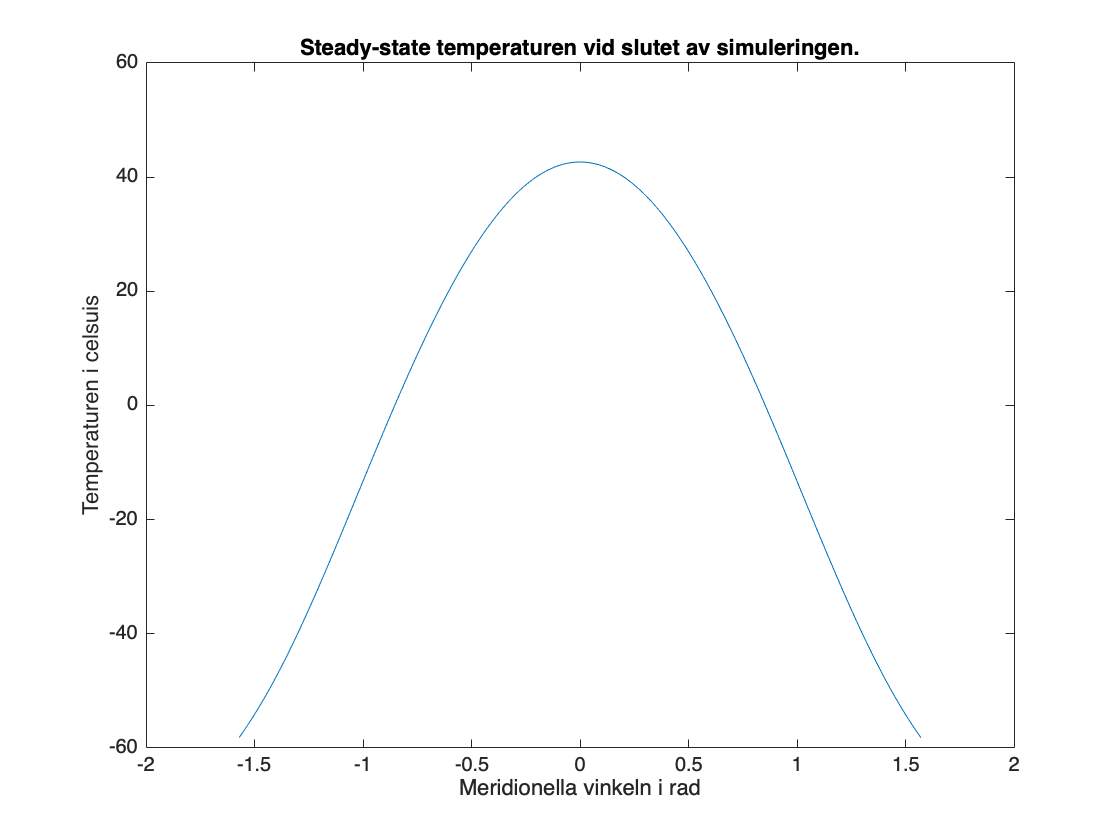


% figure(2)
% hold on 
% plot(timeVec,Tmatrix(:,1))
% plot(timeVec,Tmatrix(:,2))
% plot(timeVec,Tmatrix(:,90))
% plot(timeVec,Tmatrix(:,end))
% 
% %legend('-90', '-89', '89')
% legend('-90 deg','-89 deg','0 deg', '90 deg')

figure(3)
plot(lat, Tmatrix(end,:)-273)
xlabel('Meridionella vinkeln i rad') 
ylabel('Temperaturen i celsuis')
title('Steady-state temperaturen vid slutet av simuleringen.')

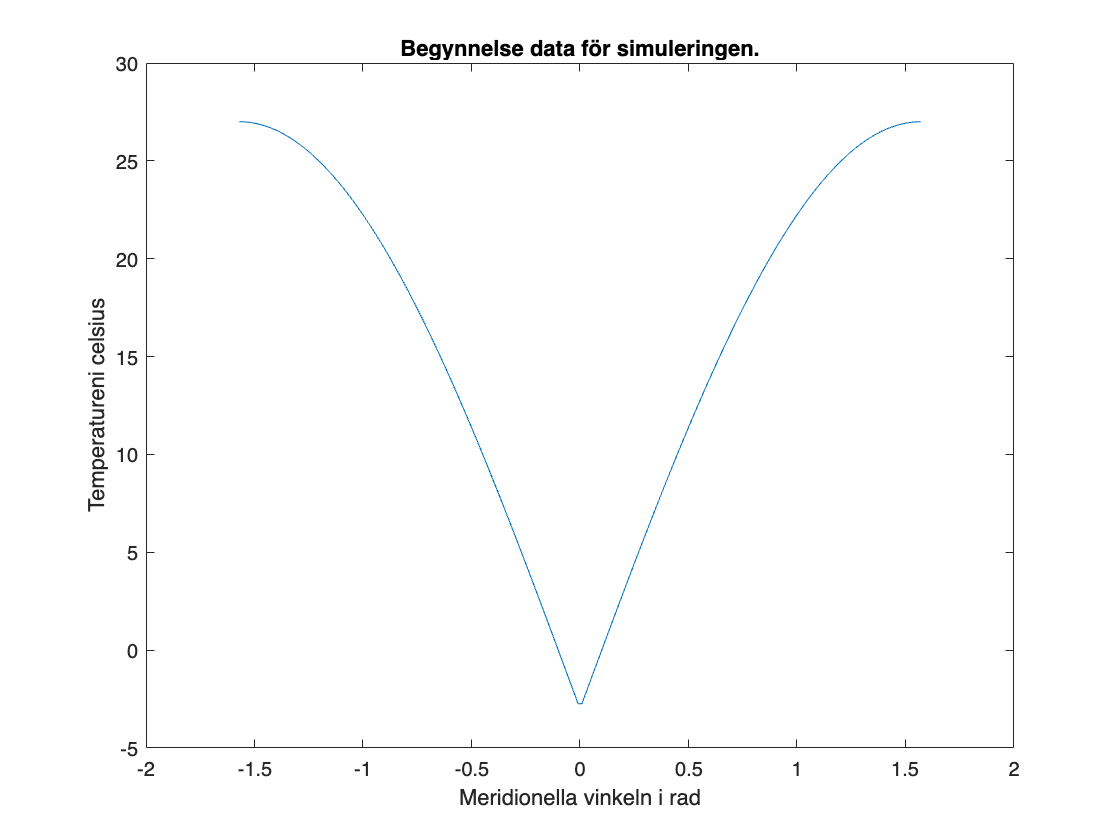

figure(4)
plot(lat, Tmatrix(1,:)-273)
xlabel('Meridionella vinkeln i rad') 
ylabel('Temperatureni celsius')
title('Begynnelse data för simuleringen.')